## Known values are defined:

t = 4;                          %mm - thickness
w = 6.5;                        %mm - width
I = (t*(w^3-4^3))/12;           %mm^4 Second moment of area - cross section of the hole
c = w/2;                        %mm - distance to neutral axis
kt = 2.0767;                    %Stress concentration factor
L = 25;                         %mm - length of arm

sigma_y = 60.67;                % MPa = N/mm^2 POM
SF = 2;                         % Safety factor

syms F_LS                       % Symbolic definition of Leadscrew Force

### Minimal angle

p_min = 4;                      %mm - half of lowest pitch distance at fully closed
theta_min = asind((p_min/L))

theta_min = 9.2069

theta = theta_min : 0.5 : 90;   %Angle vektor

phi =2*theta;

## Stresses

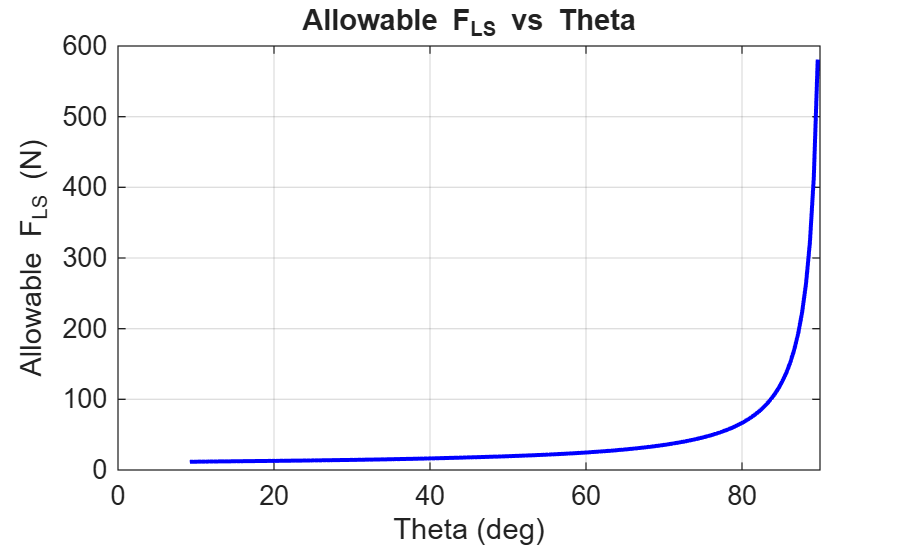

%Definition of tension force
T = (F_LS/2)./(sind(theta));    %2 comes from 2 scissors, so the force is equally divided by the two links

%Tension force as components in the binding link's local coordinate system.
F_axial_local = -T .* cosd(phi);
F_trans_local =  -T .* sind(phi);

M = abs(L .* F_trans_local);    %Moment (absolute value to always get positve stress

sigma_bend = ( (M*c)/I ).* kt;
sigma_axial = (F_axial_local ./ (t*w) ) * kt;

sigma_side_1 = sigma_axial + sigma_bend;
sigma_side_2 = sigma_axial - sigma_bend;

sigma_max = max(abs(sigma_side_1), abs(sigma_side_2));

%% Allowable force
sigma_allow = sigma_y ./ SF;

sigma_per_N = double(subs(sigma_max,F_LS,1));   %Finds max stress per unit force [N]

F_LS_allow = sigma_allow ./ sigma_per_N;        %Finds allowable force with respect to yields stress

figure;
plot(theta, F_LS_allow, 'b-', 'LineWidth', 1.5);
xlim([0 90]);
xlabel('Theta (deg)');
ylabel('Allowable F_{LS} (N)');
title('Allowable F_{LS} vs Theta');
grid on;

%% Leadscrew torque

p_lead = 4;                                     % mm/rev, change to actual lead screw lead
eta = 0.5;                                      % efficiency, estimate

T_allow_Nmm = F_LS_allow .* p_lead ./ (2*pi*eta);
T_allow_Nm = T_allow_Nmm ./ 1000;

[T_crit, idx] = min(T_allow_Nm)

T_crit = 0.0148

idx = 1

theta_crit = theta(idx)

theta_crit = 9.2069

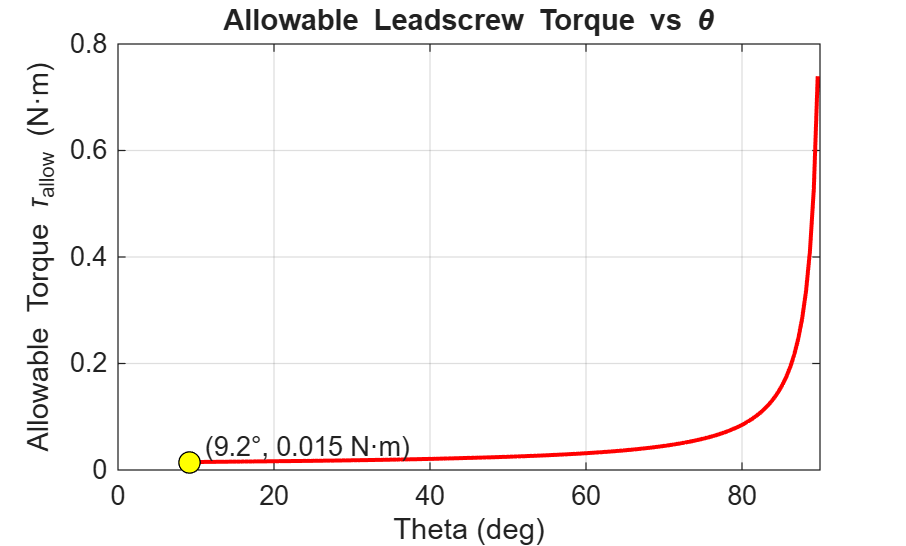

% Plot T_allow_Nm vs theta
figure;
plot(theta, T_allow_Nm, 'r-', 'LineWidth', 1.5);
xlim([0 90]);
xlabel('Theta (deg)');
ylabel('Allowable Torque \tau_{allow} (N·m)');
title('Allowable Leadscrew Torque vs \theta');
grid on;
hold on;
% Mark critical point
plot(theta_crit, T_crit, 'ko', 'MarkerFaceColor','y','MarkerSize',8);
text(theta_crit, T_crit, sprintf('  (%.1f°, %.3f N·m)', theta_crit, T_crit), 'VerticalAlignment','bottom');
hold off;